## TS4

P1

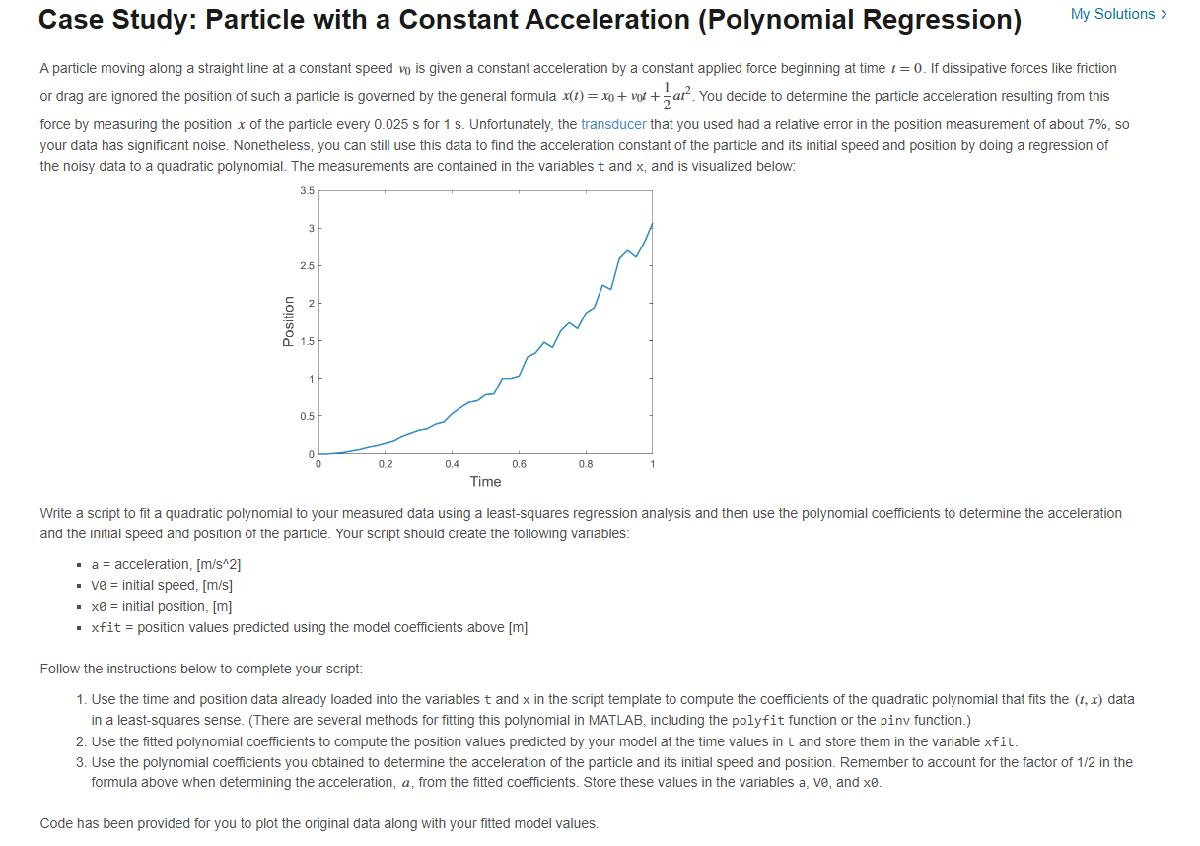

%{
load measurements

% Fit the data with a regression to a quadratic polynomial.
coeffs = polyfit(t, x, 2); % Ajuste cuadrático: coeffs = [a/2, v0, x0]

% Compute the fitted model values.
xfit = polyval(coeffs, t);

% Obtain the physical model coefficients.
a = 2 * coeffs(1); % El coeficiente cuadrático es a/2
v0 = coeffs(2);
x0 = coeffs(3);

%%%%%%%%%%%%% Plotting Code Below %%%%%%%%%%%%%%%
% Plot the results.
plot(t, x, 'ro', t, xfit, 'b');
xlabel('time [s]');
ylabel('position [m]');
title('Position of a particle under constant acceleration');
legend('Measured data', 'Fitted model', 'Location', 'Best');
grid on;

% Print the results.
fprintf('.\n');
fprintf(' a = %5.3f [m/s^2]\n', a); 
fprintf('v0 = %5.3f [m/s]\n', v0); 
fprintf('x0 = %.3e [m]\n', x0);
%}

P2

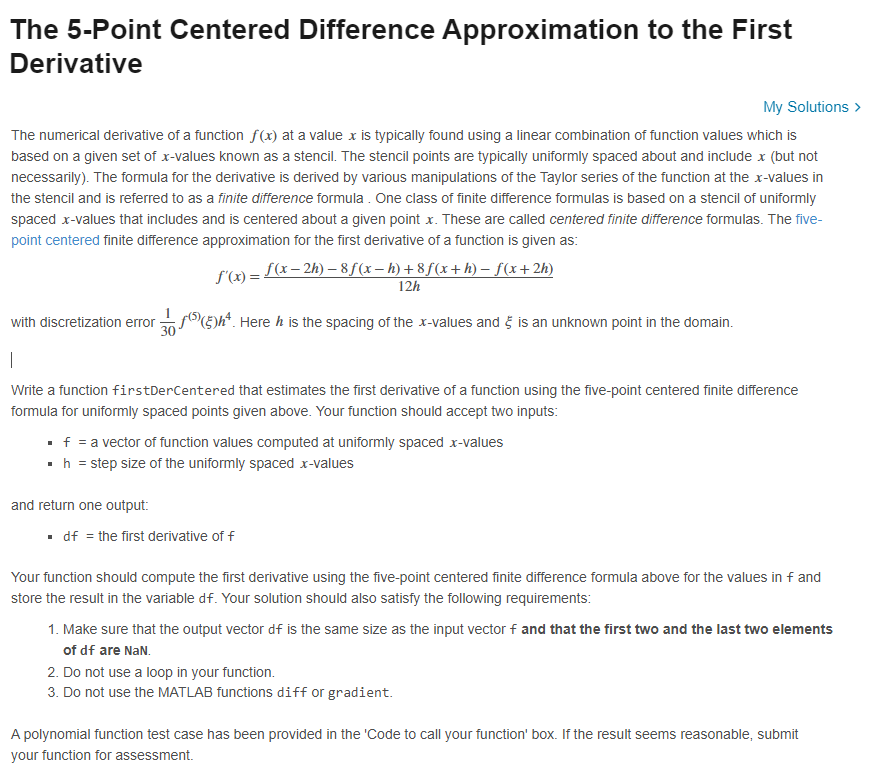

%{
function  df = firstDerCentered(f,h)

% Compute the 5 point centered finite difference vector df.
% Make sure the first and last two values of df are NaN.
    % Inicializar el vector df con NaN
    df = NaN(size(f));
    
    % Aplicar la fórmula de 5 puntos centrada de manera vectorizada
    df(3:end-2) = (f(1:end-4) - 8*f(2:end-3) + 8*f(4:end-1) - f(5:end)) / (12*h);
    end
%}
h = 0.1;
x = 0:h:0.7;
f = 1 + x + x.^4;
df = firstDerCentered(f,h)

df =                  NaN                 NaN   1.032000000000000   1.107999999999999   1.255999999999999   1.500000000000000                 NaN                 NaN


P3

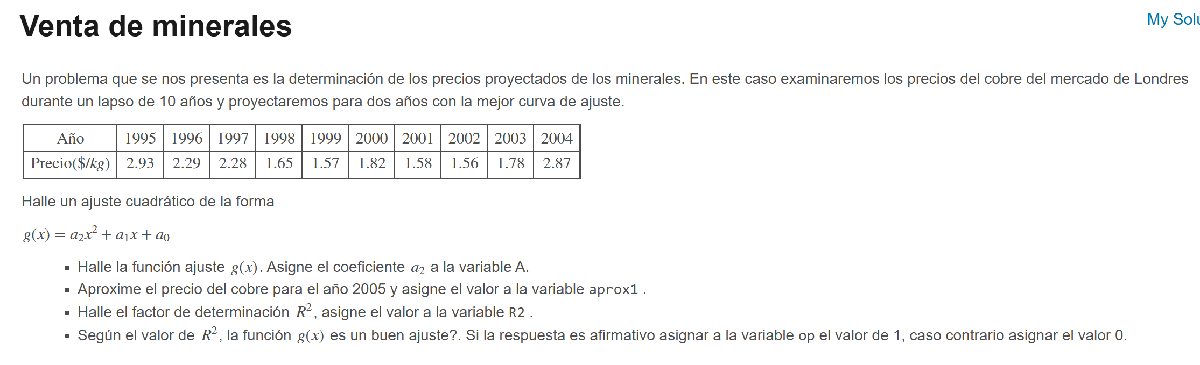

format long
% Datos
t = (1:10)';
precio = [2.93 2.29 2.28 1.65 1.57 1.82 1.58 1.56 1.78 2.87]';

% Ajuste cuadrático
p = polyfit(t, precio, 2)

p =    0.060037878787879  -0.706901515151516   3.609500000000003


a2 = p(1)

a2 =    0.060037878787879


A = a2

A =    0.060037878787879


a1 = p(2);
a0 = p(3);

% Aproximación del precio para el año 2005 (t = 11)
aprox1 = polyval(p, 11);

% Cálculo de R^2 para el ajuste cuadrático
y_pred = polyval(p, t);
St = sum((precio - mean(precio)).^2);  % Variación total
Sr = sum((precio - y_pred).^2);        % Variación del error
R2 = 1 - (Sr / St)  % Coeficiente de determinación

R2 =    0.822192261649761



% Verificación del ajuste
op = double(R2 > 0.7)

op =      1



% Mostrar resultados
disp('Coeficientes del polinomio cuadrático:');

Coeficientes del polinomio cuadrático:


disp(['a2 = ', num2str(a2)]);

a2 = 0.060038


disp(['a1 = ', num2str(a1)]);

a1 = -0.7069


disp(['a0 = ', num2str(a0)]);

a0 = 3.6095


disp(['Aproximación para t=11: ', num2str(aprox1)]);

Aproximación para t=11: 3.0982


disp(['R^2: ', num2str(R2)]);

R^2: 0.82219


disp(['¿El ajuste es bueno? (1 = sí, 0 = no): ', num2str(op)]);

¿El ajuste es bueno? (1 = sí, 0 = no): 1


P4

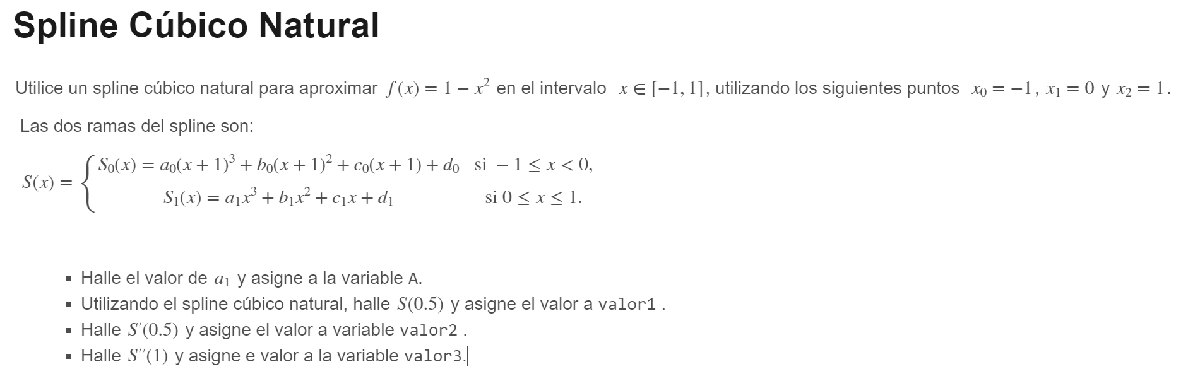

format long
x=[-1 0 1]

x =     -1     0     1


y=[0 1 0]

y =      0     1     0



S = splinenatural(x,y)

S =   -0.500000000000000                   0   1.500000000000000                   0
   0.500000000000000  -1.500000000000000                   0   1.000000000000000



a1 = S(2,1); % coeficiente a1
A = a1; a0 = S(1,1); b0=S(1,2); c0=S(1,3);d0=S(1,4);
b1 =S(2,2); c1=S(2,3); d1=S(2,4);

syms x
S1 = a1*x^(3)+b1*x^2+c1*x+d1

$$S1 = \frac{x^{3}}{2}-\frac{3\,x^{2}}{2}+1$$


valor1 = double(subs(S1,x,0.5))

valor1 =    0.687500000000000



S1_1_dif = diff(S1,x)

$$S1\_1\_dif = \frac{3\,x^{2}}{2}-3\,x$$

valor2 = double(subs(S1_1_dif,x,0.5))

valor2 =   -1.125000000000000


S1_2_dif = diff(S1_1_dif,x)

$$S1\_2\_dif = 3\,x-3$$

valor3 = double(subs(S1_2_dif,x,1))

valor3 =      0


%use la funcion de spline cubico natural trabajada en clase
%{
function S = splinenatural(X,Y)
    N=length(X)-1; H=diff(X); E=diff(Y)./H;
    diagprinc=2*(H(1:N-1)+H(2:N)); diagsupinf=H(2:N-1);
    g0=0; gn=0;
    A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b=6*diff(E'); g=A\b;
    g=[g0 g' gn];
    figure(7); clf;
    for i=1:N
        S(i,1)=(g(i+1)-g(i))/(6*H(i));
        S(i,2)=g(i)/2;
        S(i,3)= E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4)=Y(i);
        xx=linspace(X(i),X(i+1),100);
        yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy,'LineWidth',2), hold on
    end
    plot(X,Y,'or','MarkerSize',10,'LineWidth',2);
    grid on, hold off
end
%}

P5

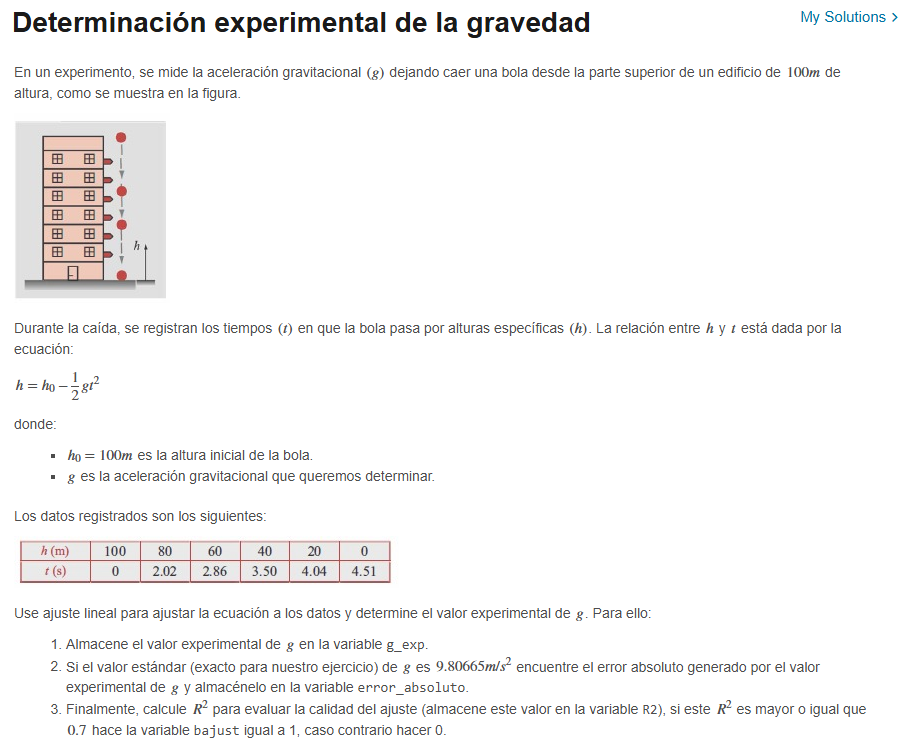

format long
% Datos experimentales
h = [100, 80, 60, 40, 20, 0]; % Alturas en metros
t = [0, 2.02, 2.86, 3.50, 4.04, 4.51]; % Tiempos en segundos

% Ajuste lineal para determinar g
h0=100;
y_aj = h0-h

y_aj =      0    20    40    60    80   100


x_aj = t.^2

x_aj =                    0   4.080400000000000   8.179599999999999  12.250000000000000  16.321600000000000  20.340100000000000


p = polyfit(x_aj,y_aj,1)

p =    4.912426136086927  -0.083576311478097



g_exp = 2*p(1)

g_exp =    9.824852272173853


% Realice el ajuste lineal


% Calcular el error absoluto
g_real = 9.80665; % Valor estándar de g en m/s^2
error_absoluto = abs(g_real-g_exp)

error_absoluto =    0.018202272173854



% Calcular R^2
y_pred = polyval(p,x_aj);
St = sum((y_aj - mean(y_aj)).^2);  % Variación total
Sr = sum((y_aj - y_pred).^2);        % Variación del error
R2 = 1 - (Sr / St)  % Coeficiente de determinación

R2 =    0.999991008640912



% Verificación del ajuste


% Definir la variable bajust
if R2 >= 0.7
    bajust = 1
else
    bajust = 0
end

bajust =      1


P6 

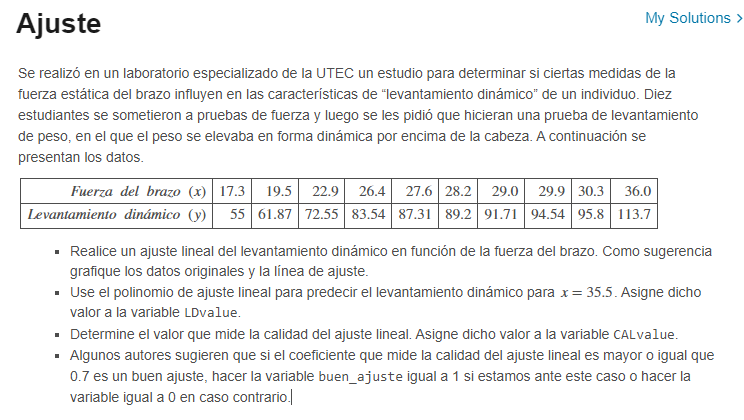

format long %complete abajo donde sea necesario
% Datos iniciales: coordenadas x e y
x = [17.3 19.5 22.9 26.4 27.6 28.2 29 29.9 30.3 36.0];
y = [55 61.87 72.55 83.54 87.31 89.2 91.71 94.54 95.8 113.7];
% Graficar los datos como puntos discretos
figure;
scatter(x, y, 'ro', 'filled'); 
hold on;
xlabel('Fuerza del brazo (x)');
ylabel('Levantamiento dinámico (y)');
title('Ajuste Lineal de Levantamiento Dinámico vs Fuerza del Brazo');

% Ajuste lineal 
p = polyfit(x, y, 1) % Encuentra coeficientes de ajuste [pendiente, intercepto]

p =    3.139879531764971   0.655817706557661



% Graficar la línea de ajuste
x_fit = linspace(min(x), max(x), 100); % Valores de x para la línea de ajuste
y_fit = polyval(p, x_fit); % Evaluación del polinomio ajustado
plot(x_fit, y_fit, 'b', 'LineWidth', 2);

% Calcular un valor específico (35.5) usando el modelo lineal ajustado
% LDvalue es el valor estimado de y para x = 35.5
LDvalue = polyval(p, 35.5)

LDvalue =      1.121215410842141e+02



% Cálculo del coeficiente de determinación R^2
y_pred = polyval(p, x); % Valores ajustados para los datos originales
SStotal = sum((y - mean(y)).^2); % Suma total de los cuadrados
SSres = sum((y - y_pred).^2); % Suma de los cuadrados de los residuos
CALvalue = 1 - (SSres / SStotal); % Coeficiente de determinación R^2

% Evaluar si el ajuste es bueno según el criterio: R^2 >= 0.7
buen_ajuste = 0; % Inicializar la variable de control
if CALvalue >= 0.7
    buen_ajuste = 1; % Indica que el ajuste es bueno
else
    buen_ajuste = 0; % Indica que el ajuste no es bueno
end

% Mostrar los resultados
fprintf('LDvalue = %.4f\n', LDvalue);

LDvalue = 112.1215


fprintf('CALvalue (R^2) = %.4f\n', CALvalue);

CALvalue (R^2) = 1.0000


fprintf('buen_ajuste = %d\n', buen_ajuste);

buen_ajuste = 1


P7

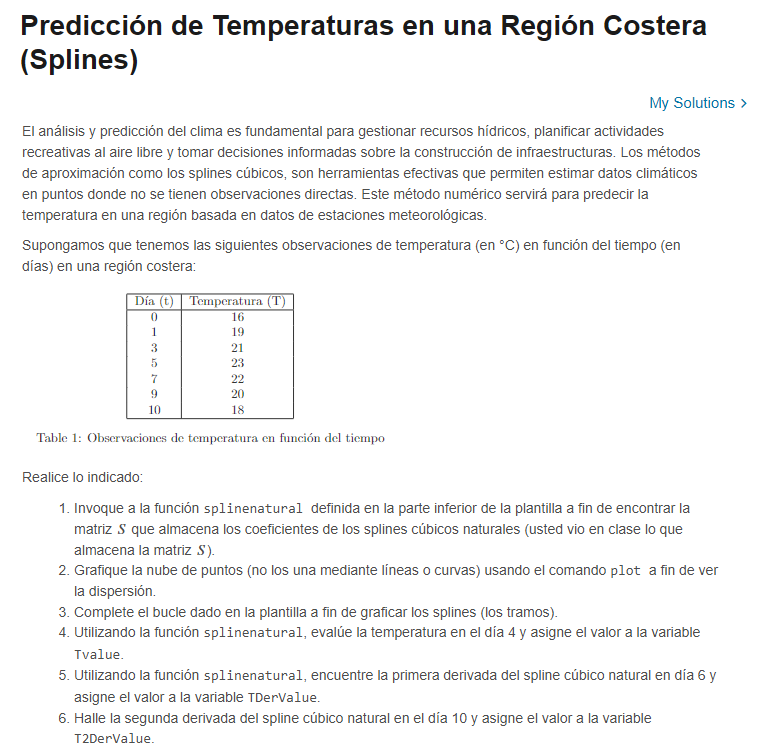

format long

% Datos en forma de vector fila
t = [0 1 3 5 7 9 10];
T = [16 19 21 23 22 20 18];

% Llamar a la función de spline cúbico natural definida en la parte inferior
S = splinenatural(t, T)

S =   -0.385167464114833                   0   3.385167464114832  16.000000000000000
   0.270334928229665  -1.155502392344498   2.229665071770335  19.000000000000000
  -0.196172248803828   0.466507177033493   0.851674641148325  21.000000000000000
   0.139354066985646  -0.710526315789474   0.363636363636364  23.000000000000000
  -0.111244019138756   0.125598086124402  -0.806220095693780  22.000000000000000
   0.180622009569378  -0.541866028708134  -1.638755980861244  20.000000000000000


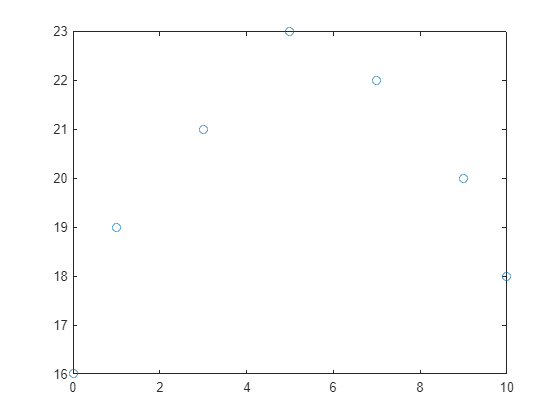


% Graficar la nube de puntos (sin unirlos con líneas)
plot(t, T,'o'); 



% Graficar el spline a manera de ayuda
for i = 1:length(t) - 1
    xx = linspace(t(i), t(i+1), 100); % Generar 100 puntos en el intervalo [ti, ti+1]
    yy = S(i,1)*(xx - t(i)).^3 + S(i,2)*(xx - t(i)).^2 + S(i,3)*(xx - t(i)) + S(i,4);
    plot(xx, yy);
end
hold off;

% Evaluar la temperatura en el día 4
Tvalue = evalSpline(t, S, 4);
fprintf('Temperatura en el día 4: %.4f°C\n', Tvalue);

Temperatura en el día 4: 22.1220°C



% Evaluar la primera derivada del spline en el día 6
TDerValue = evalSplineDeriv(t, S, 6);
fprintf('Primera derivada en el día 6: %.4f\n', TDerValue);

Primera derivada en el día 6: -0.6394



% Evaluar la segunda derivada del spline en el día 10
T2DerValue = evalSplineSecondDeriv(t, S, 10);
fprintf('Segunda derivada en el día 10: %.4f\n', T2DerValue);

Segunda derivada en el día 10: 0.0000


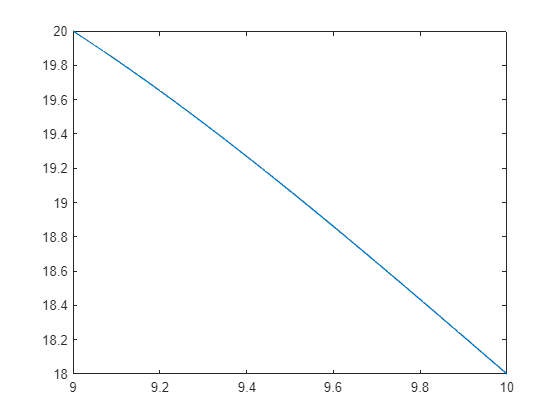


hold off;


%{
function S = splinenatural(X, Y)
    % Número de intervalos
    N = length(X) - 1; 
    
    % Diferencias entre los puntos
    H = diff(X); 
    E = diff(Y) ./ H;
    
    % Construcción de la matriz del sistema
    diagprinc = 2 * (H(1:N-1) + H(2:N)); 
    diagsupinf = H(2:N-1);
    
    % Condiciones de frontera naturales (segunda derivada cero)
    g0 = 0; 
    gn = 0;
    
    % Matriz A y vector b
    A = diag(diagprinc) + diag(diagsupinf, 1) + diag(diagsupinf, -1);
    b = 6 * diff(E'); 
    g = A \ b;
    g = [g0; g; gn];
    
    % Coeficientes del spline
    S = zeros(N, 4);
    for i = 1:N
        S(i,1) = (g(i+1) - g(i)) / (6 * H(i));
        S(i,2) = g(i) / 2;
        S(i,3) = E(i) - H(i) * (g(i+1) + 2 * g(i)) / 6;
        S(i,4) = Y(i);
    end
end

%% Función para evaluar el spline en un punto x
function val = evalSpline(X, S, x)
    i = find(X <= x, 1, 'last'); % Encontrar el intervalo correcto
    if i == length(X), i = i - 1; end % Si x está en el último nodo, ajustamos
    dx = x - X(i);
    val = S(i,1)*dx^3 + S(i,2)*dx^2 + S(i,3)*dx + S(i,4);
end

%% Función para evaluar la primera derivada del spline en un punto x
function val = evalSplineDeriv(X, S, x)
    i = find(X <= x, 1, 'last'); 
    if i == length(X), i = i - 1; end
    dx = x - X(i);
    val = 3*S(i,1)*dx^2 + 2*S(i,2)*dx + S(i,3);
end

%% Función para evaluar la segunda derivada del spline en un punto x
function val = evalSplineSecondDeriv(X, S, x)
    i = find(X <= x, 1, 'last'); 
    if i == length(X), i = i - 1; end
    dx = x - X(i);
    val = 6*S(i,1)*dx + 2*S(i,2);
end
%}

P8

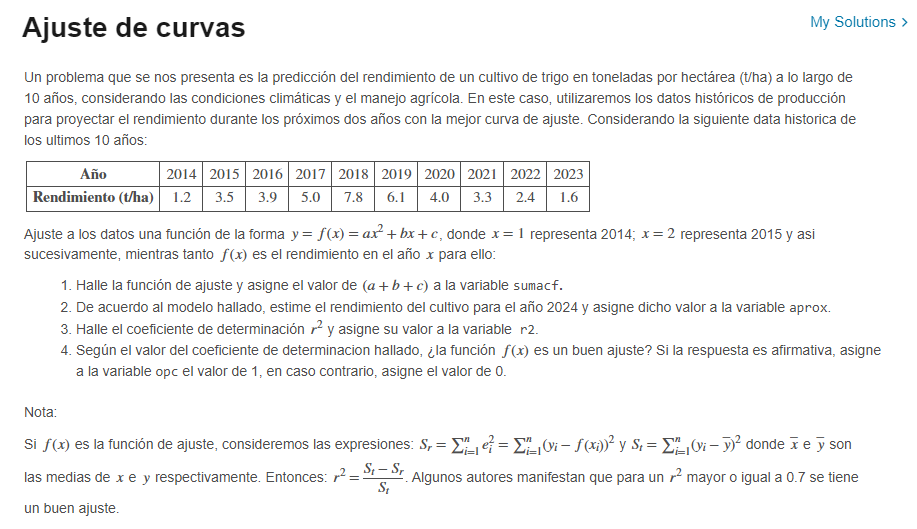

format long
% Datos históricos
anios = 2014:2023; % Años
rendimientos = [1.2, 3.5, 3.9, 5.0, 7.8, 6.1, 4.0, 3.3, 2.4, 1.6]; % Rendimientos

% Transformar años para x (2014 = 1, 2015 = 2, ..., 2023 = 10)
x = 1:length(anios);

% Ajuste de curva cuadrática: y = ax^2 + bx + c
p = polyfit(x, rendimientos, 2); % Encuentra coeficientes a, b, c
a = p(1);
b = p(2);
c = p(3);

% Suma de los coeficientes a + b + c
sumacf = a + b + c

% Estimar rendimiento para 2024 (x = 11)
x_pred = 11;
aprox = polyval(p, x_pred)

% Calcular r^2
y_ajuste = polyval(p, x); % Valores ajustados con el modelo
y_media = mean(rendimientos);
St = sum((rendimientos - y_media).^2);
Sr = sum((rendimientos - y_ajuste).^2);
r2 = (St - Sr) / St

% Determinar si el ajuste es bueno
opc = double(r2 >= 0.7) % Si r^2 > 0.7, el ajuste es bueno (1), si no, es malo (0)



P9

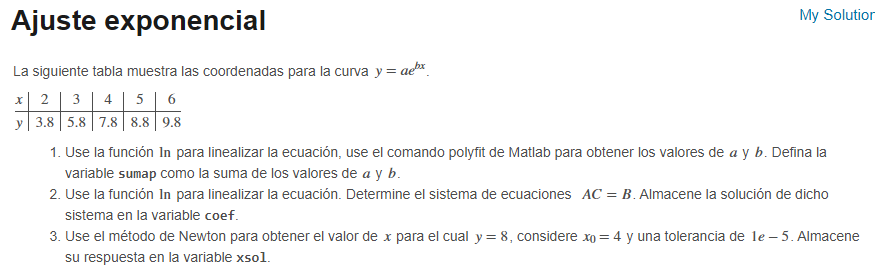

% Datos iniciales
x = [2, 3, 4, 5, 6]; % Vector de datos para x
y = [3.8, 5.8, 7.8, 8.8, 9.8]; % Vector de datos para y

% Parte 1: Transformación logarítmica y ajuste polinomial
Y = log(y); % Transformación logarítmica de y

I = ones(length(x), 1); % Vector de unos
M = [I, x'] % Matriz de diseño con una columna de unos y x

M =      1     2
     1     3
     1     4
     1     5
     1     6


A = M' * M; % Matriz del sistema normal de ecuaciones
B = M' * Y'; % Vector de términos independientes
coef = A \ B % Resolución del sistema para obtener los coeficientes

coef =    0.996160788300127
   0.231165644182015


a = exp(coef(1)) % Coeficiente a después de exponenciar

a =    2.707865776567805


b = coef(2) % Coeficiente b

b =    0.231165644182015



% Parte 2: Solución mediante el método de mínimos cuadrados

p = polyfit(x, Y, 1) % Ajuste lineal a los datos transformados

p =    0.231165644182016   0.996160788300124


b = p(1) % Coeficiente de la pendiente

b =    0.231165644182016


a = exp(p(2)) % Coeficiente del término constante después de exponenciar

a =    2.707865776567797


sumap = a + b % Suma de a y b

sumap =    2.939031420749813


% Parte 3: Método de Newton para encontrar la raíz de la función
syms x_var
f = a * exp(b * x_var) - 8; % Función que queremos resolver f(x) = 0
x0 = 4; % Valor inicial
Tol = 1e-5; % Tolerancia
xsol = newton(f, x0, Tol) % Llamada al método de Newton

xsol =    4.000000000000000
   4.743581109272986
   4.686546069097746
   4.686166757423541
   4.686166740792818


xsol= xsol(end)

xsol =    4.686166740792818



% Función para el método de Newton
%{
function z = newton(f, x0, Tol)
    syms x % Definición de x simbólica dentro de la función
    df = diff(f, x); % Derivada de la función f
    f = matlabFunction(f, 'Vars', x); % Conversión de f simbólica a una función numérica
    dfu = matlabFunction(df, 'Vars', x); % Conversión de la derivada a función numérica
    z = x0; % Inicialización de z con el valor inicial
    error = 1; % Error inicial mayor que Tol
    while error > Tol
        x1 = x0 - f(x0) / dfu(x0); % Fórmula del método de Newton
        z = [z; x1]; % Almacenamiento del nuevo valor de x
        error = abs(x1 - x0) / abs(x1); % Cálculo del error relativo
        x0 = x1; % Actualización de x0 para la siguiente iteración
    end
end
%}

P10

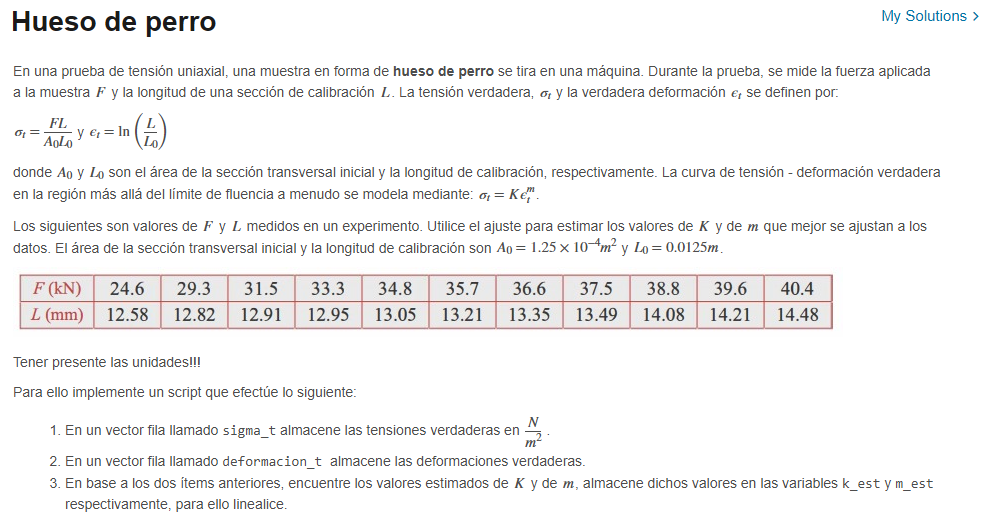

format long
%ingrese sus datos, tener presente que es necesario una conversión de unidades
% Valores de fuerza (kN) y longitud (mm) del problema
F = [24.6, 29.3, 31.5, 33.3, 34.8, 35.7, 36.6, 37.5, 38.8, 39.6, 40.4] * 1000; % Convertir a Newtons
L = [12.58, 12.82, 12.91, 12.95, 13.05, 13.21, 13.35, 13.49, 14.08, 14.21, 14.48] * 1e-3; % Convertir a metros

% Datos iniciales del problema
A0 = 1.25e-4; % Área de la sección inicial (m²)
L0 = 0.0125; % Longitud inicial (m)

% Cálculo de la tensión verdadera sigma_t
sigma_t = (F .*L / (A0 * L0)) % En N/m² (Pascales)

sigma_t = 1.0e+08 *

   1.980595200000000   2.404006400000000   2.602656000000000   2.759904000000000   2.906496000000000   3.018220800000000   3.127104000000000   3.237600000000000   3.496345599999999   3.601382400000000   3.743948800000001



% Cálculo de la deformación verdadera epsilon_t
deformacion_t = log(L / L0)

deformacion_t =    0.006379606964039   0.025277807184268   0.032273560550296   0.035367143837291   0.043059489460447   0.055245474225978   0.065787740538003   0.076220025911409   0.119026706421641   0.128217297800754   0.147039742649315



% Ajuste lineal para encontrar K y m en la ecuación sigma_t = K * epsilon_t^m
X = log(deformacion_t); % Logaritmo de epsilon_t
Y = log(sigma_t); % Logaritmo de sigma_t

% Realizar ajuste lineal Y = mX + log(K)
p = polyfit(X, Y, 1);
m_est = p(1) % Pendiente = m

m_est =    0.208527705033086


k_est = exp(p(2)) % K = exp(intersección)

k_est =      5.494757831313617e+08


Funciones

function S = splinenatural(X,Y)
    % Número de intervalos
    N = length(X) - 1; 
    
    % Diferencias entre los puntos
    H = diff(X); 
    E = diff(Y) ./ H;
    
    % Construcción de la matriz del sistema
    diagprinc = 2 * (H(1:N-1) + H(2:N)); 
    diagsupinf = H(2:N-1);
    
    % Condiciones de frontera
    g0 = 0; 
    gn = 0;
    
    % Matriz A y vector b
    A = diag(diagprinc) + diag(diagsupinf, 1) + diag(diagsupinf, -1);
    b = 6 * diff(E'); 
    g = A \ b;
    g = [g0; g; gn];
    
    % Coeficientes del spline
    S = zeros(N, 4);
    for i = 1:N
        S(i,1) = (g(i+1) - g(i)) / (6 * H(i));
        S(i,2) = g(i) / 2;
        S(i,3) = E(i) - H(i) * (g(i+1) + 2 * g(i)) / 6;
        S(i,4) = Y(i);
    end
end
%% Función para evaluar el spline en un punto x
function val = evalSpline(X, S, x)
    i = find(X <= x, 1, 'last'); % Encontrar el intervalo correcto
    if i == length(X), i = i - 1; end % Si x está en el último nodo, ajustamos
    dx = x - X(i);
    val = S(i,1)*dx^3 + S(i,2)*dx^2 + S(i,3)*dx + S(i,4);
end

%% Función para evaluar la primera derivada del spline en un punto x
function val = evalSplineDeriv(X, S, x)
    i = find(X <= x, 1, 'last'); 
    if i == length(X), i = i - 1; end
    dx = x - X(i);
    val = 3*S(i,1)*dx^2 + 2*S(i,2)*dx + S(i,3);
end

%% Función para evaluar la segunda derivada del spline en un punto x
function val = evalSplineSecondDeriv(X, S, x)
    i = find(X <= x, 1, 'last'); 
    if i == length(X), i = i - 1; end
    dx = x - X(i);
    val = 6*S(i,1)*dx + 2*S(i,2);
end
function M = minimoscuadrados(xdata,ydata)
    A = [ sum(xdata.^0) sum(xdata.^1)
      sum(xdata.^1) sum(xdata.^2) ]
    b = [ sum((xdata.^0).*ydata)
          sum((xdata.^1).*ydata) ]
    % te da [a0, a1]
    coef = A\b
    % Estimación de la recta:
    yh = coef(1) + coef(2)*xdata;
    
    figure(1); clf;
    xx = xdata(1):0.1:xdata(end);
    yy = coef(1) + coef(2)*xx;
    plot(xdata,ydata,'xr','MarkerSize',12,'LineWidth',2); grid on; hold on;
    plot(xdata,yh,'om','MarkerSize',12,'LineWidth',2);
    plot(xx,yy,'-b'); 
    xlabel('Eje X'); ylabel('Eje Y')
    St = sum((ydata - mean(ydata)).^2)
    Sr = sum((ydata - yh).^2)
    R2 = 1 - Sr/St
    M = R2;
end

function  df = firstDerCentered(f,h)

% Compute the 5 point centered finite difference vector df.
% Make sure the first and last two values of df are NaN.
    % Inicializar el vector df con NaN
    df = NaN(size(f));
    
    % Aplicar la fórmula de 5 puntos centrada de manera vectorizada
    df(3:end-2) = (f(1:end-4) - 8*f(2:end-3) + 8*f(4:end-1) - f(5:end)) / (12*h);
end
% Función para el método de Newton
function z = newton(f, x0, Tol)
    syms x % Definición de x simbólica dentro de la función
    f = matlabFunction(f); % Conversión de f simbólica a una función numérica
    df = diff(f(x)); % Derivada de la función f
    dfu = matlabFunction(df); % Conversión de la derivada a función numérica
    z = x0; % Inicialización de z con el valor inicial
    error = 1; % Error inicial mayor que Tol
    while error > Tol
        x1 = x0 - f(x0) / dfu(x0); % Fórmula del método de Newton
        z = [z; x1]; % Almacenamiento del nuevo valor de x
        error = abs(x1 - x0) / abs(x1); % Cálculo del error relativo
        x0 = x1; % Actualización de x0 para la siguiente iteración
    end
end